%Aufgabe 2
%Daten laden
file = fullfile("cars.csv");
T = readtable(file);
%Daten vorbereiten und Ausschnitt darstellen
disp(head(T));

    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin      origin2                  name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    ___________    _____________________________

    18         8            307            130         3504           12         70       1       {'Amerika'}    {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'Amerika'}    {'buick skylark 320'        }
    18         8            318            150         3436           11         70    

catOrigin = categorical(T.origin2);
B = onehotencode(catOrigin, 2);
df = table2array(T(:, 2:7));

%MPG als Vektor speichern
YTrain = table2array(T(:, 1));
%Größe des Vektors speichern für Designmatrix
nYTrain = size(YTrain, 1);
%Designmatrix aus Merkmalen 2-7 plus die Indikatormatrix von Merkmal 8
XTrain = [df, B];
%Einsen-Vektor hinzufügen
DTrain = [XTrain, ones(nYTrain, 1)];
%Lambda für Einheitsmatrix zur Verhinderung von singulärer Matrix
lambda = 0.00001;
wb = linsolve(DTrain' * DTrain + lambda*eye(10), DTrain'*YTrain);

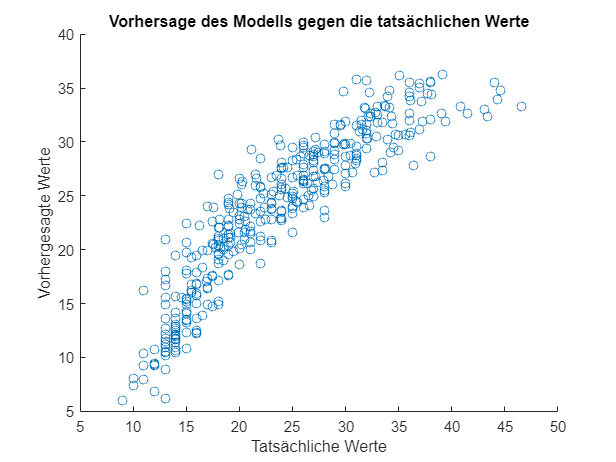

YTrainPred = DTrain * wb; 
scatter(YTrain, YTrainPred);
title(sprintf("Vorhersage des Modells gegen die tatsächlichen Werte"));
xlabel(sprintf("Tatsächliche Werte"));
ylabel(sprintf("Vorhergesagte Werte"));

RMSETrain = sqrt(mean( (YTrain - YTrainPred).^2 ))

RMSETrain = 3.2684

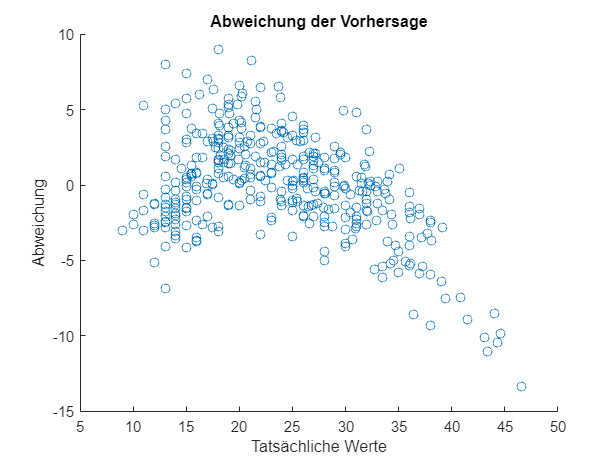


deviation = YTrainPred - YTrain;

scatter(YTrain, deviation)
title(sprintf("Abweichung der Vorhersage"));
xlabel(sprintf("Tatsächliche Werte"));
ylabel(sprintf("Abweichung"));